# 题目：评价下表中20条河流的水质情况

注意：含氧量越高越好，PH值越接近7越好，细菌总数越少越好，植物性营养物量介于10-20之间最好

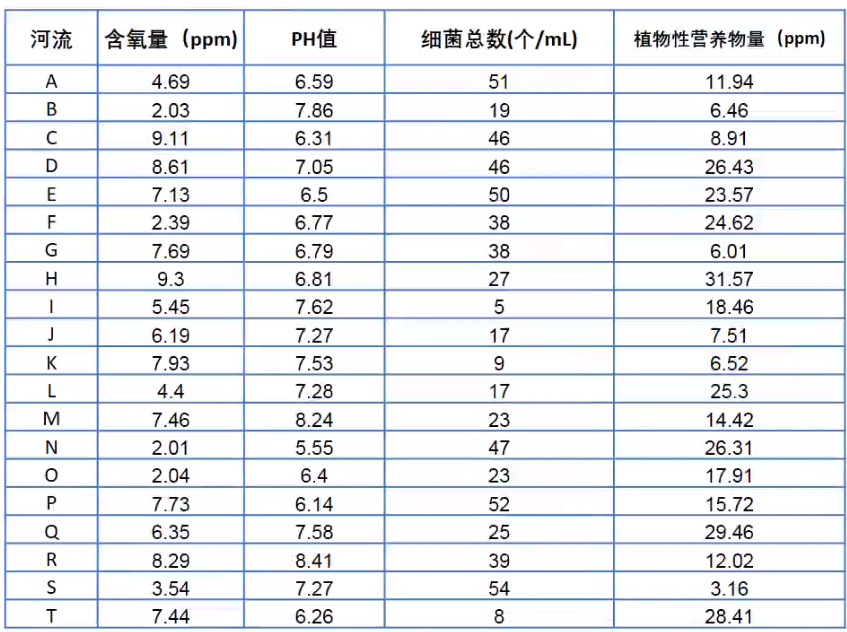

data1 = [4.69 2.03 9.11 8.61 7.13 2.39 7.69 9.3 5.45 6.19 7.93 4.4 7.46 2.01 2.04 7.73 6.35 8.29 3.54 7.44]';
data2 = [6.59 7.86 6.31 7.05 6.5 6.77 6.79 6.81 7.62 7.27 7.53 7.28 8.24 5.55 6.4 6.14 7.58 8.41 7.27 6.26]';
data3 = [51 19 46 46 50 38 38 27 5 17 9 17 23 47 23 52 25 39 54 8]';
data4 = [11.94 6.46 8.91 26.43 23.57 24.62 6.01 31.57 18.46 7.51 6.52 25.3 14.42 26.31 17.91 15.72 29.46 12.02 3.16 28.41]';

%指标2由中间型转化为极大型
data2 = mid2max(data2, 7);

%指标3由极小型转化为极大型
data3 = max(data3) - data3;

%指标4由区间型转化为极大型
data4 = inter2max(data4, [10 20]);

%将所有指标（列）横向并为一个矩阵
A = [data1 data2 data3 data4];

%标准化
A = stand(A);

%计算评价对象得分(加权)，效果同 s = objscore(A);
s = objscore(A, [0.25 0.25 0.25 0.25]');

%标准化
s = normal(s)

s =     0.0416
    0.0380
    0.0476
    0.0468
    0.0448
    0.0372
    0.0543
    0.0483
    0.0719
    0.0799



M = max(s);
idx = find(M == s)

idx = 11